# Prvi domaći zadatak iz predmeta spektralna analiza signala

Dragana Ninković 2019/0052

## Uvod

clear; close all; clc;

% osnovne dimenzije
Nf=512;
Nr=50;
N=256;
fig=1;

% genersianje frekvencija
f = linspace(-0.5,0.5,Nf);

% ucitavanje fajla
FileName = 'x4.csv';
data = csvread(FileName);

## 1) Procenjivanje SGSS na osnovu jedne realizacije

Metode su date u zip folderu a ovde je samo na grafiku demonstriran njihov rad.

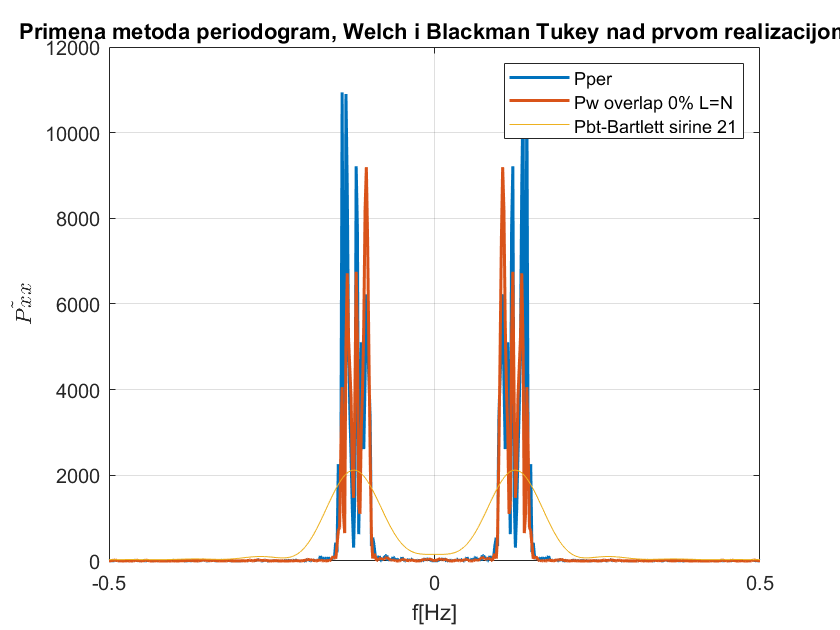

figure(fig)
 plot(f,Pper(data(1,:),f),'LineWidth',1.5);
 hold all;
 plot(f,Pw(data(1,:),f,256,0),'LineWidth',1.5);
 plot(f,Pbt(data(1,:),f,bartlett(21)))
 grid on;title('Primena metoda periodogram, Welch i Blackman Tukey nad prvom realizacijom')
 legend('Pper','Pw overlap 0% L=N','Pbt-Bartlett sirine 21');
 xlabel('f[Hz]');ylabel('$\tilde{Pxx}$', 'Interpreter','latex');hold off;

fig=fig+1;

## 2) Periodogrami prvih pet realizacija

Primetimo da spektar ima mnogo parova pikova u zavisnosti od realizacije, ali ti pikovi su uvek u opsegu oko [0.1,0.2]. Samim tim zaključujemo da imamo signal koji liči na jednu ili zbir više sinusoida u tom opsegu. S obzirom da se na krajevima stacionira na nenultu vrednost znamo da postoji i neki šum. Pojava sporednih manjih pikova može biti posledica curenja spektra usled računanja furijeove transformacije u konačnom broju tačaka, ali s obzirom da za neke od realizacija sporedni pikovi nisu zanemarljivi u odnosu na srednji, moze biti u pitanju i vise sinusoida koje su na jako bliskim učestanostima i razmazano su se preklopile usled curenja spektra. Iz ovog razloga za sve pikove koji nisu zanemarljivi potrudićemo se da ostanu vidljivi.

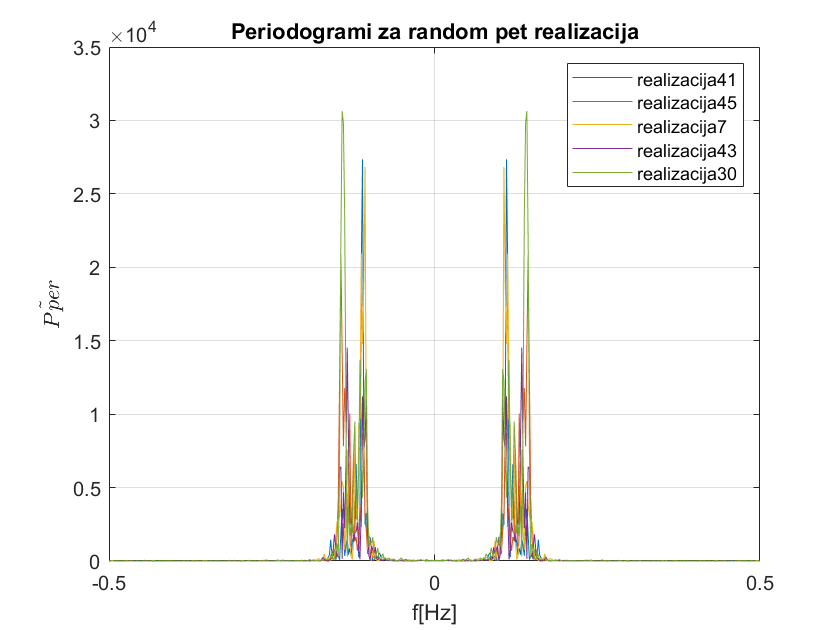

Pper_=zeros(Nr,Nf);

for i = 1:Nr
     Pper_(i,:)=Pper(data(i,:),f);
end

ids = randperm(50,5);
figure(fig)
   plot(f,Pper_(ids(1),:),'LineWidth',0.5)
   hold on;
   plot(f,Pper_(ids(2),:),'LineWidth',0.5)
   hold on;
   plot(f,Pper_(ids(3),:),'LineWidth',0.5)
   hold on;
   plot(f,Pper_(ids(4),:),'LineWidth',0.5)
   hold on;
   plot(f,Pper_(ids(5),:),'LineWidth',0.5)
   grid on;title('Periodogrami za random pet realizacija');
   xlabel('f[Hz]');ylabel('$\tilde{Pper}$', 'Interpreter','latex');
   legend(['realizacija',num2str(ids(1))],['realizacija',num2str(ids(2))],...
       ['realizacija',num2str(ids(3))],['realizacija',num2str(ids(4))],...
       ['realizacija',num2str(ids(5))])
   hold off;

 fig=fig+1;

## 3) Zatvaranje prozora - Blackman Tukey

Da bi spektar Rxx održao sve bitne osobine nakon množenja prozorskom funkcijom bitno je da vazi:

- 0<=  w[k]  <= w[0]

- w[0] = 1

- w[-k] = w[k]

- w[k] = 0 za abs(k)>M

Zbog toga biramo Bartlett-ovu prozorsku funkciju (koja je jedna od prozorskih funkcija koje ispunjavaju ove uslove). Kada povećavamo M varijansa će da poraste jer je približno linearno srazmerna M. $var\tilde{P_{bt}}(f)=\frac{P_{xx}(f)}{N}*\sum_{-M}^{M}w^2[k]\approx\frac{P_{xx}(f)}{N}*\frac{2*M}{3}$

Nasuprot tome, širina loba će da se  poveća samim tim i curenje spektra. Iz tog razloga, potrebno je da uzmemo najmanje M za koje se komponente signala idalje raspoznaju.

Po preporuci za veliko N se moze uzeti oko $M=\frac{N}{5}$ što je u našem slučaju 51, pa možemo pokušati sa tom vrednošću i par vrednosti manjih i većih od nje, kao i graničnim slučajevima M=N i M=1. Vidimo da se za 51 ne raspoznaju jasno dva pika. Za M=256 ima dosta pikova ali deluje da se ističu 3. Kako smanjujemo M upadljiva su 3 pika. Za M=65 se razaznaju samo 2 pika, za M=71 se razaznaju 3 al su skoro pa spojena. Iz tog razloga kao optimalno M uzimamo 81, kao premalo 21, a kao preveliko 256.

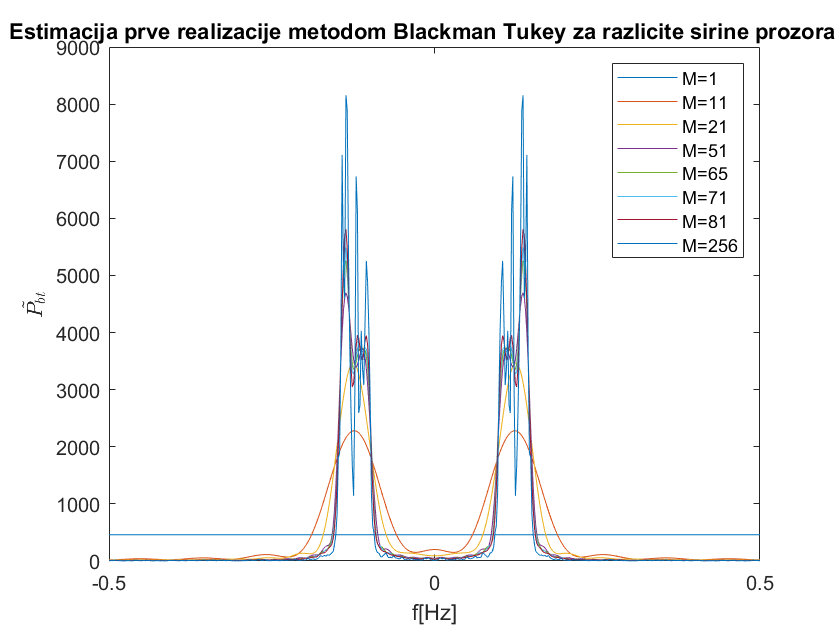

m=[1,11,21,51,65,71,81,256];
Nm=length(m);

for i = 1:Nm 
    figure(fig)
        plot(f,Pbt(data(1,:),f,bartlett(2*m(i)+1)),'LineWidth',0.5)
        hold on;      
end
 figure(fig)
     title('Estimacija prve realizacije metodom Blackman Tukey za razlicite sirine prozora M')
     xlabel('f[Hz]');ylabel('$\tilde{P_{bt}}$', 'Interpreter','latex');
     legend('M=1','M=11','M=21','M=51','M=65','M=71','M=81','M=256');

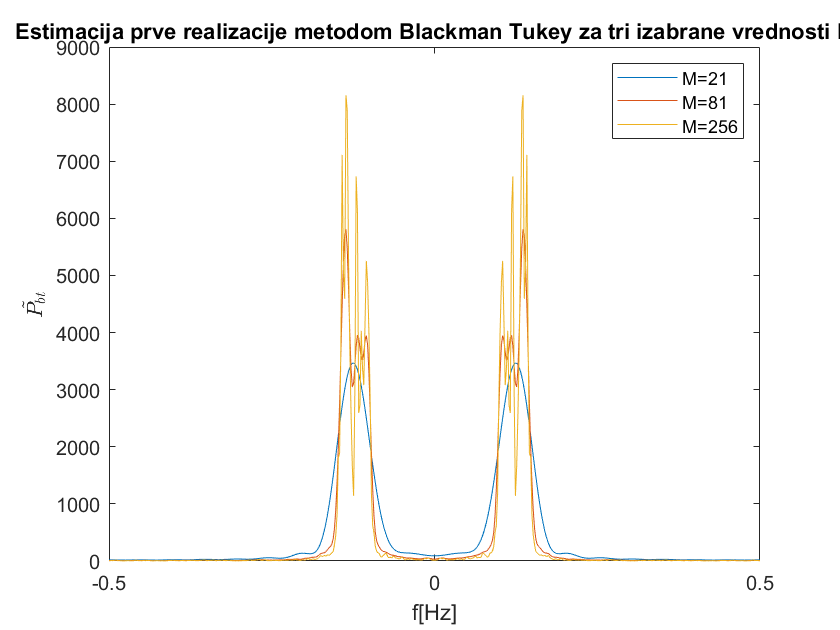

     fig=fig+1;

     
for M =[21,81,256]
   w=bartlett(2*M+1);
   figure(fig)
     plot(f,Pbt(data(1,:),f,w),'LineWidth',0.5)
     hold on
end
title('Estimacija prve realizacije metodom Blackman Tukey za tri izabrane vrednosti M');
xlabel('f[Hz]');ylabel('$\tilde{P_{bt}}$', 'Interpreter','latex');
legend('M=21','M=81','M=256')
hold off;

fig=fig+1;

## 4) Zatvaranje prozora - Welch-ov metod

Kod Welch-ovog metoda, što se u većem broju odbiraka sekvence preklapaju to ćemo dobiti veći broj sekvenci pa će se faktor kojim delimo varijansu povećati. S druge strane što se više preklapaju korelisanost će biti veća pa usred toga nećemo imati samo sumu varijansi već na to još i sumu kovarijansi što povećava ukupnu varijansu. Iz ovog razloga treba napraviti kompromis izmedju ova dva zahteva.

Kada povećavamo dužinu smanjuje se širina glavnog loba prozorske funkcije koja je posledica konačnog broja trenutaka u kojima računamo furijeovu transformaciju, čime dolazi do manjeg razmazivanja ali i do manjeg broja sekvenci što smanjuje poboljšanje varijanse.

Zato, biramo L tako da bude najmanje moguće da se raspoznaju komponente.

Za L mozemo probati stepene broja 2 pošto je dužina sekvence 256, a za overlap mozemo probati 0.4-0.9 s obzirom da znamo da je odgovarajući overlap uglavnom izmedju 50 i 70 %

L = [1,2,8,16,32,64,180,128];
overlap_p=[0.4,0.5,0.6,0.7,0.8,0.9];
Nl=length(L);

## biranje L

Za L<= 128 vide se samo 1-2 pika , a na 256 se vidi previše pikova, tako da možemo dodati par tačaka izmedju ove dve učestanosti da vidimo da li postoji neka na kojoj su uočljiva tri pika. Vidimo da se na L=180 vide tri pika pa nju možemo uzeti kao željenu, L=32 kao premalu a L=256 kao preveliku.

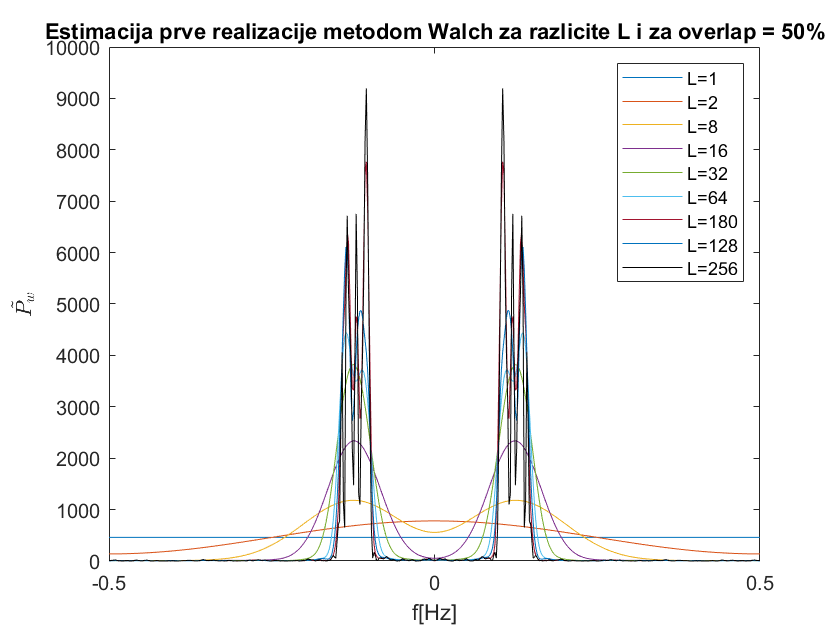

legend_=strings(Nl+1,1);
for i = 1:Nl   
    figure(fig)
       plot(f,Pw(data(1,:),f,L(i),floor(0.5*L(i))), 'LineWidth',0.5)
       hold on;
       legend_(i)=['L=',num2str(L(i))];
 end
    figure(fig)
       plot(f,Pw(data(1,:),f,N,0),'k', 'LineWidth',0.5)
       hold on;
       legend_(Nl+1)='L=256';
       title('Estimacija prve realizacije metodom Walch za razlicite L i za overlap = 50%')
       xlabel('f[Hz]');ylabel('$\tilde{P_{w}}$', 'Interpreter','latex');
       legend(legend_);

    fig=fig+1;

## prikaz izabranih parametara

 L_=[32,180,256];
 overlap=[0,0.6,0.9];
 k=1;

## prikaz izabranih L

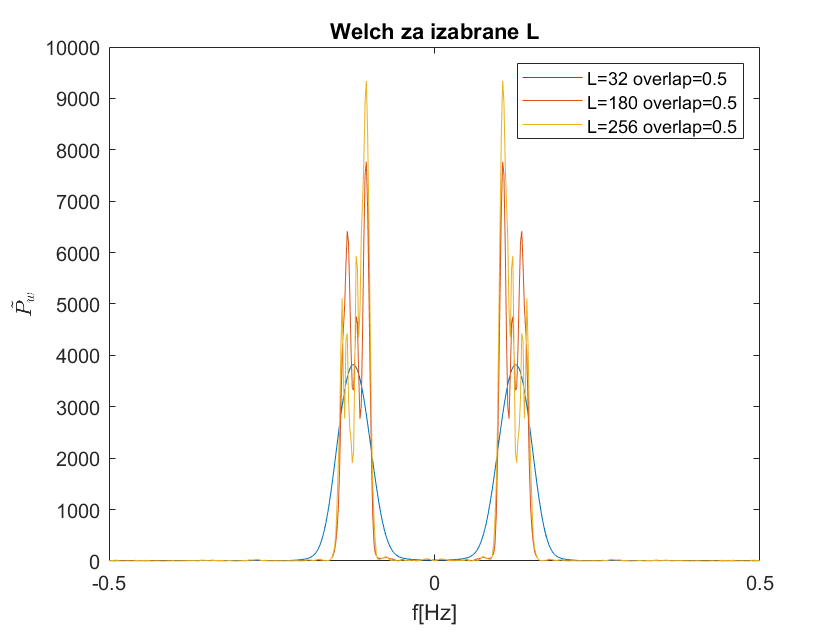

 legend_=strings(3,1);
  figure(fig)
  for i = 1:3
          plot(f,Pw(data(1,:),f,L_(i),floor(0.5*L_(i))))
          hold on;
          legend_(i)=['L=',num2str(L_(i)),' overlap=0.5'];
  end
  figure(fig)
  title('Welch za izabrane L');
  xlabel('f[Hz]');ylabel('$\tilde{P_{w}}$', 'Interpreter','latex');
  legend(legend_);

  fig=fig+1;

## prikaz za izabrane overlap-ove

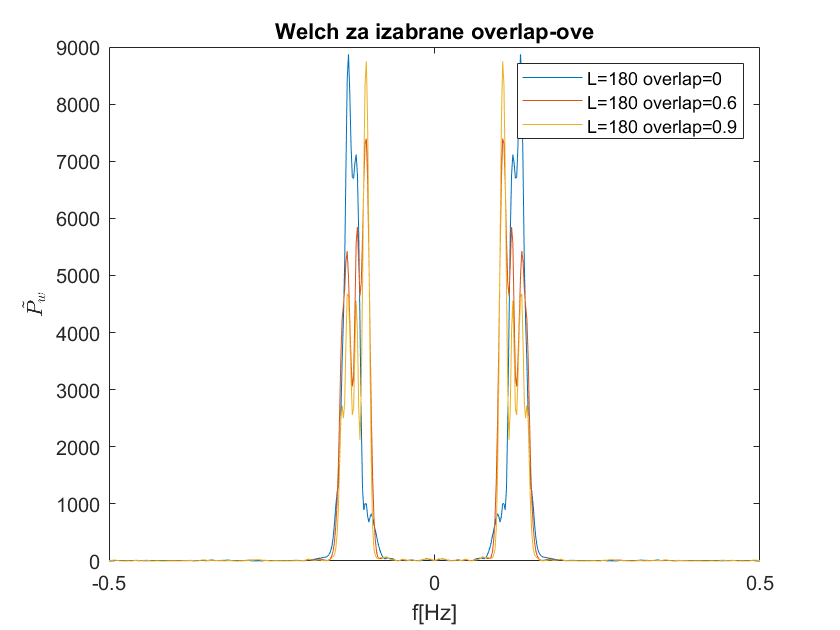

 figure(fig)
  for i = 1:3
          plot(f,Pw(data(1,:),f,180,floor(overlap(i)*180)))
          hold on;
          legend_(i)=['L=180 overlap=',num2str(overlap(i))];
  end
  figure(fig)
  title('Welch za izabrane overlap-ove');
  xlabel('f[Hz]');ylabel('$\tilde{P_{w}}$', 'Interpreter','latex');
  legend(legend_);

  fig=fig+1;

## trazeni prikaz u matrici 3*3

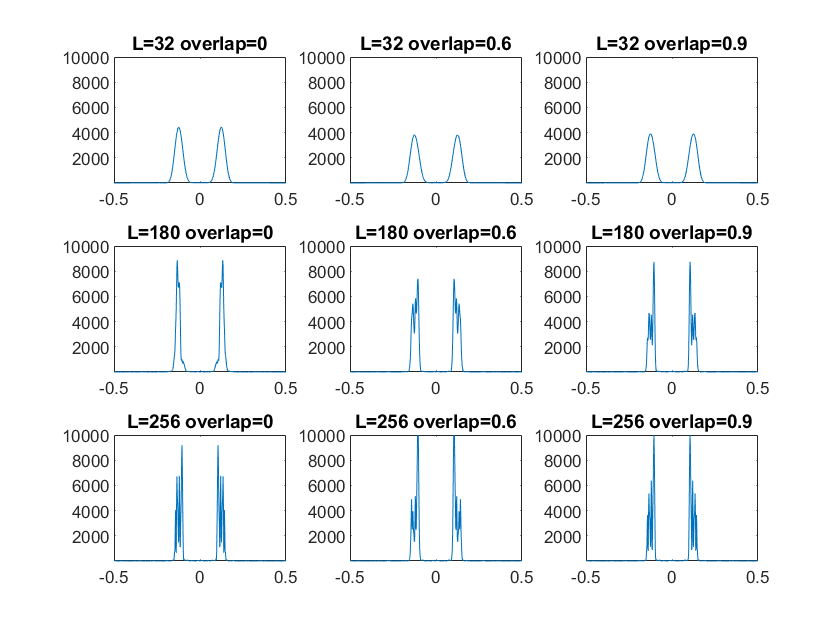

figure(fig)
  for i = 1:3
      for j = 1:3
         
          subplot(3,3,k)
          plot(f,Pw(data(1,:),f,L_(i),floor(overlap(j)*L_(i))))
          ylim([1,10000])
          title(['L=',num2str(L_(i)),' overlap=',num2str(overlap(j))])
          k=k+1;
      end
  end

fig=fig+1;

## 5)Poredjenje varijansi usrednjenih procena metoda

Periodogram ima najveću varijansu, što smo i očekivali s obzirom da bi varijansa periodograma trebala biti kvadrat prave vrednosti. Vidimo da otprilike varijansa periodograma jeste približno jednaka kvadratu srednje vrednosti.  Welch smanjuje varijansu, ali na njegovo smanjenje varijanse loše utiče što su sekvence medjusobno korelisane zbog čega će smanjenje varijanse biti manje od teorijskih K puta za usrednjeni periodogram. I konačno najveće smanjenje varijanse se ostvaruje sa Blackman Tukey metodom približno oko $\frac{3M}{2N}$ u odnosu na periodogram. Pazlika u vrednostima dobijenim medijanom je što mediana uzme neki konkretan odbirak koji je u sredini što će najverovatnije biti neki od odbiraka van opsega u kome su pikovi, i za konkretne vrednosti koje uzme mediana ovaj raspored varijansi ne važi ali u proseku važi.

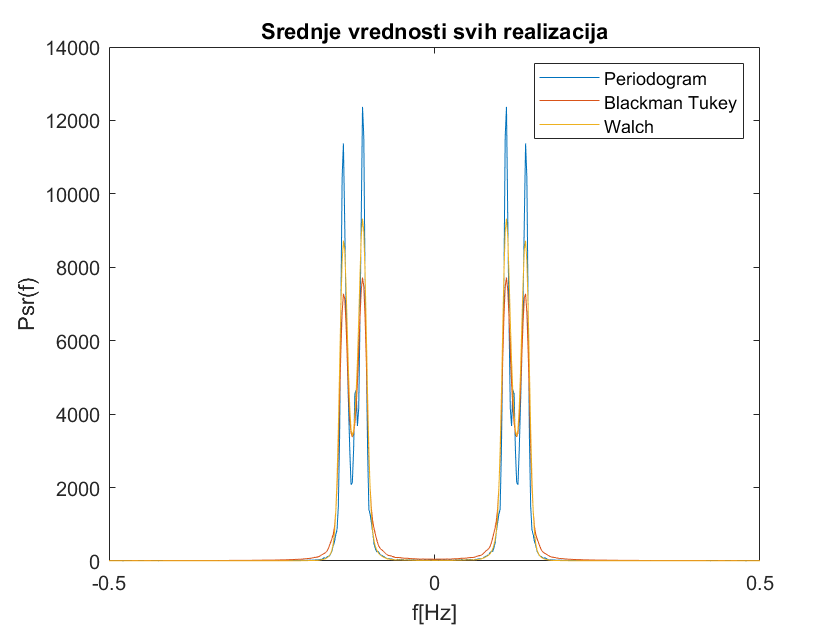

Pbt_ = zeros(Nr,Nf);
for j = 1:Nr
    Pbt_(j,:) = Pbt(data(j,:),f,bartlett(2*81+1));
end

Pw_ = zeros(Nr,Nf);
for j = 1:Nr
    Pw_(j,:) =  Pw(data(j,:),f,128,floor(0.6*128));
end

figure(fig)
plot(f,mean(Pper_,1))
hold on
plot(f,mean(Pbt_,1))
hold on;
plot(f,mean(Pw_,1))
fig=fig+1;
title('Srednje vrednosti svih realizacija')
xlabel('f[Hz]');ylabel('Psr(f)');
legend('Periodogram','Blackman Tukey','Walch');
hold off;

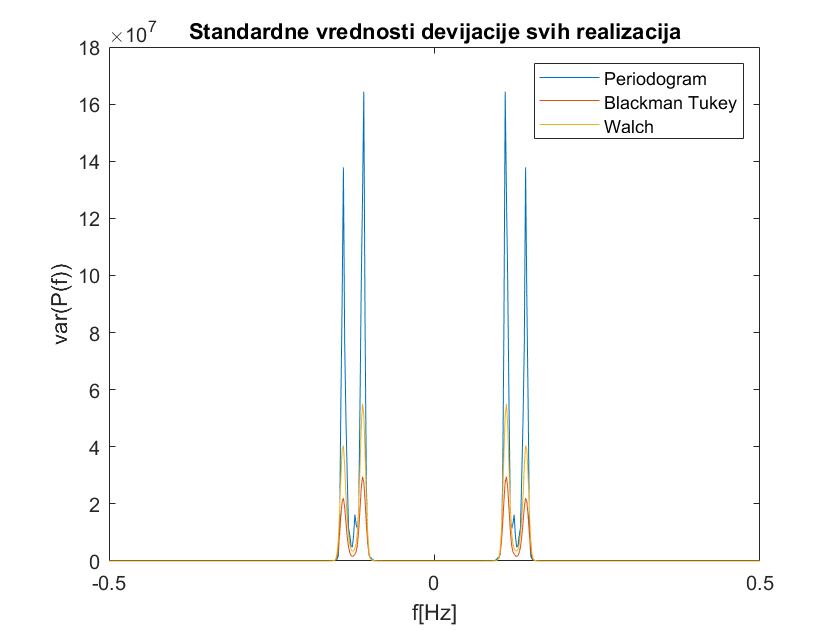


figure(fig)
plot(f,var(Pper_,0,1))
hold on
plot(f,var(Pbt_,0,1))
hold on;
plot(f,var(Pw_,0,1))
fig=fig+1;
title('Standardne vrednosti devijacije svih realizacija')
legend('Periodogram','Blackman Tukey','Walch');
hold off;
xlabel('f[Hz]');ylabel('var(P(f))');

var_medians=[median(var(Pper_,0,1));median(var(Pbt_,0,1));median(var(Pw_,0,1))];
var_means=[mean(var(Pper_,0,1));mean(var(Pbt_,0,1));mean(var(Pw_,0,1))];
methods={'periodogram';'Blackman Tukey';'Walch'};
T=table(methods,var_medians,var_means)

T = 3×3 table
         methods          var_medians    var_means 
    __________________    ___________    __________

    {'periodogram'   }      105.76       4.3695e+06
    {'Blackman Tukey'}      58.237       1.1554e+06
    {'Walch'         }      15.772       2.0928e+06


## 6) Uporedjivanje teorijskih vrednosti sa procenama

Teorijska vrednost za varijansu periodograma izvedena je pod pretpostavkom belog šuma. Ipak, ona u većini slučajeva važi i za ostale signale. Kod našeg signala dolazi do malih odstupanja od teorijske vrednosti oko pikova jer je tu spektar najmanje ravan(najrazličitiji je od spektra SGSS belog šuma). 

Blackman Tukey se poklapa sa teorijskom vrednosti osim u pikovima gde ima manju varijansu od teorijske. Ovo može biti posledica toga što je pik jako visok i uzak pa pretpostavka da je Pxx konstantno kad ga presečemo ne važi, zato odstupanje i nastaje baš kod pikova jer je donji deo krive dovoljno širok da ovo važi.

Za Welcha se dobije kao što je očekivano da ima veću varijansu od teorisjke zbog korelisanosti odbiraka.

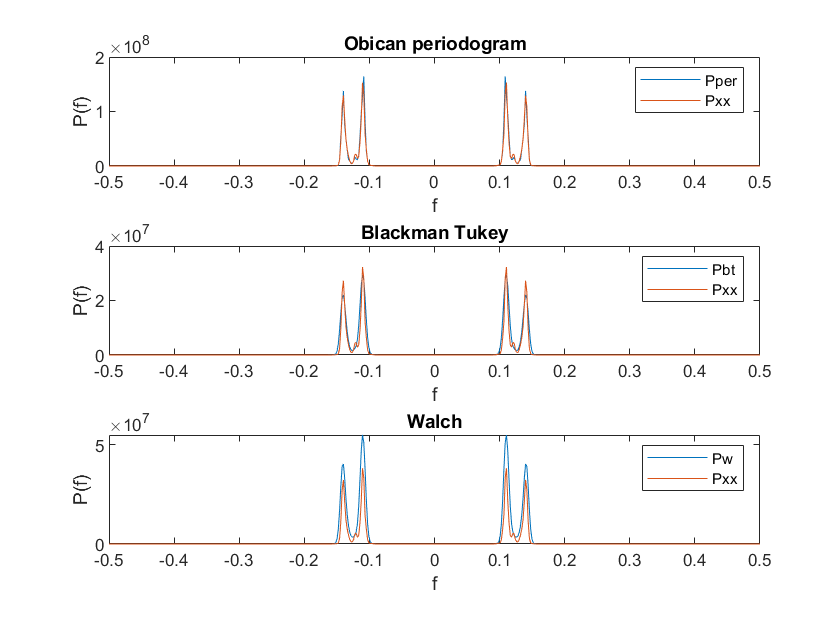

figure(fig)
title('Uporedjivanje teorijske i prave vrednosti varijanse');
subplot(3,1,1)
plot(f,var(Pper_,0,1))
hold on
plot(f,(mean(Pper_,1)).^2.*(1+(sin(2*pi*N*f)/N/sin(2*pi*f)).^2))
title('Obican periodogram');
xlabel('f'); ylabel('P(f)')
legend('Pper','Pxx')

subplot(3,1,2)
plot(f,var(Pbt_,0,1))
hold on
plot(f,mean(Pper_,1).^2/N*sum(bartlett(2*81+1).^2));
title('Blackman Tukey');
xlabel('f'); ylabel('P(f)')
legend('Pbt','Pxx')

subplot(3,1,3)
plot(f,var(Pw_,0,1))
hold on
plot(f,(mean(Pper_,1)).^2.*(1+(sin(2*pi*N*f)/N/sin(2*pi*f)).^2)/4)
title('Walch');
xlabel('f'); ylabel('P(f)')
legend('Pw','Pxx')

fig=fig+1;

## 7) Interval poverenja Blackman Tukey metode

Vidimo da usrednjena vrednost po realizacijama Pbt cela leži unutar intervala poverenja što je i očekivano. Usrednjena vrednost periodograma po realizacijama je na par mesta na granici ali većinski upada u njega.

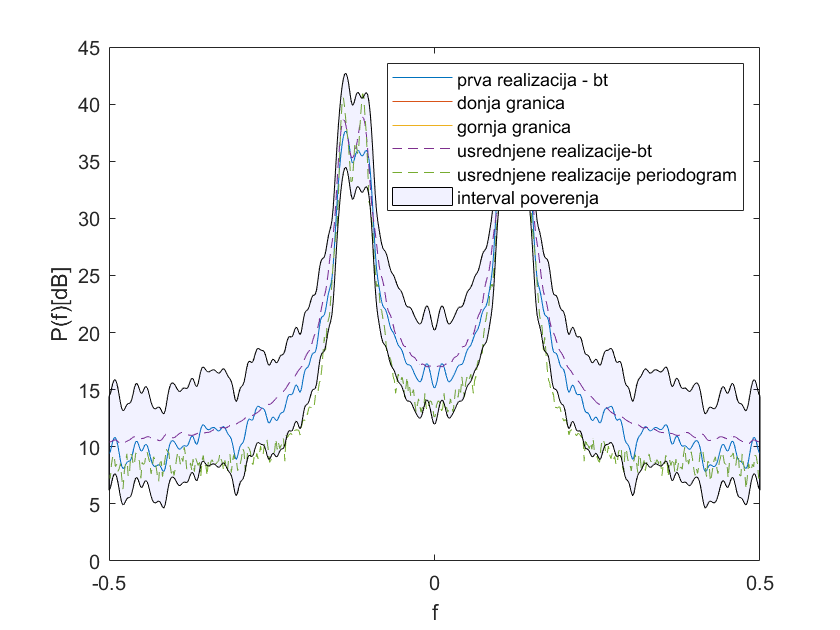

ni=2*N/sum(bartlett(2*81+1).^2);
alpha=0.05;
lower_bnd=10* log10(ni*Pbt_(1,:)/chi2inv(1-alpha/2,ni));
upper_bnd=10* log10(ni*Pbt_(1,:)/chi2inv(alpha/2,ni));

figure(fig)
plot(f,10*log10(Pbt_(1,:)))
hold all;
plot(f,lower_bnd)
plot(f,upper_bnd)
plot(f,10*log10(mean(Pbt_,1)),'--')
plot(f,10*log10(mean(Pper_,1)),'--')
patch([ f fliplr(f)],[lower_bnd fliplr(upper_bnd)],'b','FaceAlpha',0.05)
legend('prva realizacija - bt','donja granica','gornja granica','usrednjene realizacije-bt','usrednjene realizacije periodogram','interval poverenja')
fig=fig+1;
xlabel('f'); ylabel('P(f)[dB]')

## 8)

Za periodogram se varijansa dosta povećala što nije očekivano jer prava teorijska vrednost varijanse približno je jednaka kvadratu  prave vrednosti periodograma svuda sem na repovima pa bi trebala ostati nepromenjena. S obzirom da teorijski izvedena formula važi za slabostacionarne signale i izvedena je za beli šum a naš signal liči na zašumljenu sinusoidu moguće je da ovo posledica nečeg od ta dva.

Mediane opet uzimaju neke varijanse na konkretnoj frekvenciji i ne važi poredak kao za usrednjene koji vidimo sa slike.

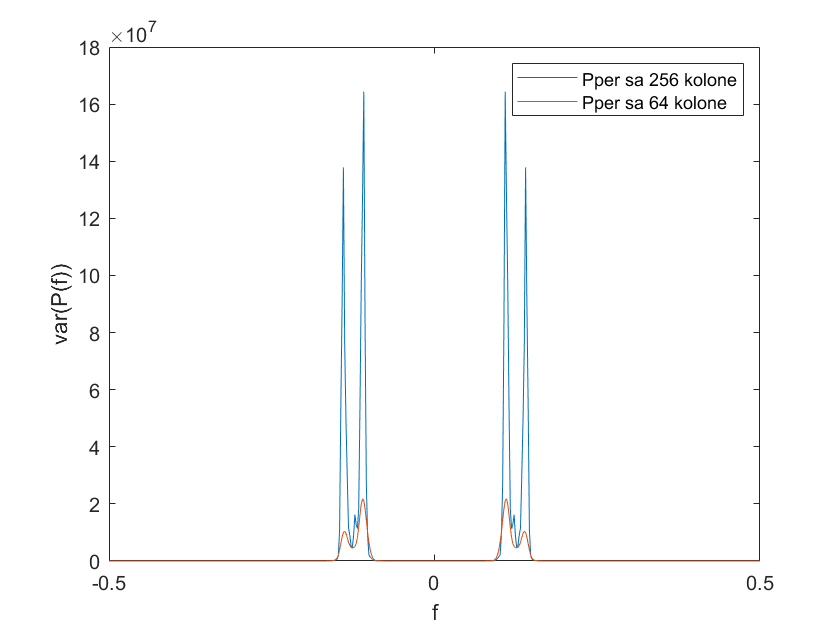

x=data(:,1:64);
Xper_=zeros(Nr,Nf);

for i = 1:Nr
     Xper_(i,:)=Pper(x(i,:),f);
end

figure(fig)
title('Uporedjivanje varijanse nakon smanjenja podataka');
plot(f,var(Pper_,0,1))
hold on
plot(f,var(Xper_,0,1))
xlabel('f'); ylabel('var(P(f))')

legend('Pper sa 256 kolone','Pper sa 64 kolone');

disp(['Mediana za 256 kolona:', num2str(median(var(Pper_,0,1)))])

Mediana za 256 kolona:105.7554


disp(['Mediana za prve 64 kolone:' ,num2str(median(var(Xper_,0,1)))])

Mediana za prve 64 kolone:286.857


disp(['Srednja vrednost varijanse za 256 kolona:', num2str(mean(var(Pper_,0,1)))])

Srednja vrednost varijanse za 256 kolona:4369532.3485


disp(['Srednja vrednost varijanse za prve 64 kolone:' ,num2str(mean(var(Xper_,0,1)))])

Srednja vrednost varijanse za prve 64 kolone:996583.3091
